# Compile Figures for Upper Kuparuk River Basin, Alaska

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


%What is your project name?
ProjFolder = 'figures/';

%What is the original data?
originaldata = {'UK_synthesized_data.txt'};

%do you want the figure saved?
printfig  = true;

%Where do you want to save files?
workdirfigures = '~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_antecedent/figures/';

%Where is your data?
workdir = '~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_antecedent';




%Set directories
workdirfig_ = {workdirfigures, ProjFolder};
workdirfig=char(strcat(workdirfig_(1),workdirfig_(2)));
if ~exist(workdirfig, 'dir')
    cd(workdirfigures)
    mkdir(ProjFolder)
end
cd(workdir)

Lets plot the results

I know the units of Q, what should the units of P be? Rainfall is at units of mm, but is that per second? The ReadMe file says precipitation is recorded hourly and nothing more. The data file says units of [mm] recorded every hour, so is it per hour? Also it says its resolution is 0.1 mm per tip. What does per tip mean?

Catchment Size of Upper Kuparuk Basin at Gauge Site is 142km^2.

From Kane:

"2007 was a relatively dry year, although all three years were below the average rainfall (222 mm). The main storage mechanism for the Upper Kuparuk is the active layer. While positive storage followed immediately after snowmelt, relative storage went from positive to negative during the summer and remained negative for the remainder of the summer as ET + Q exceeded P. The timing of this transition was later for those years with greater rainfall. Note that a large tundra wildfire in 2007 northwest of the Upper Kuparuk burned from early summer into early winter, and was the largest documented fire on the North Slope of Alaska. 

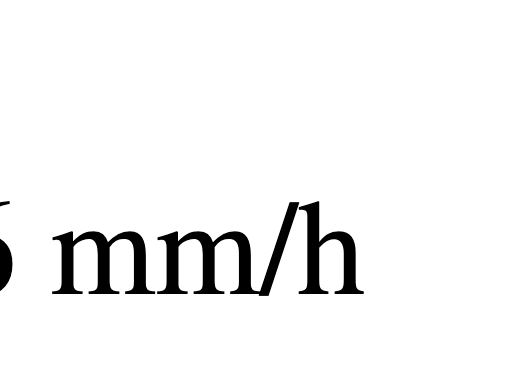

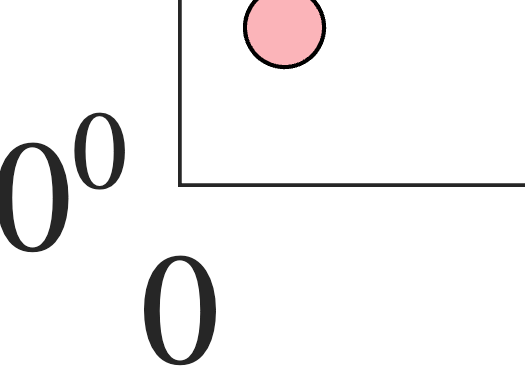

%Plot lagtime with RRD
[maxRRD,maxRRDlgt,RRD,se,lagt,colNums,lagQrange] = figtRRD_plot_antecedent('','1hr_simple_RRD.txt','1hr_simple_peakstats.txt',workdir,workdirfig,printfig);

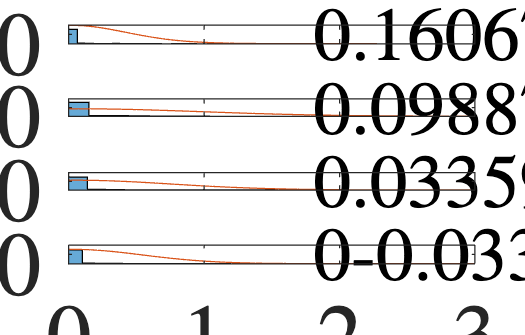

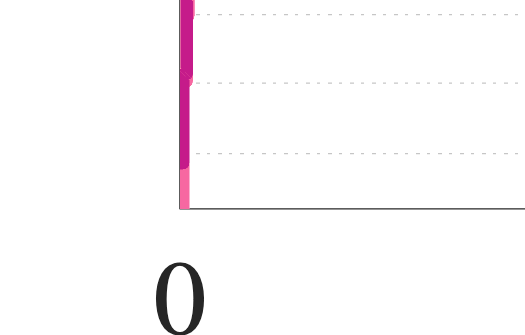

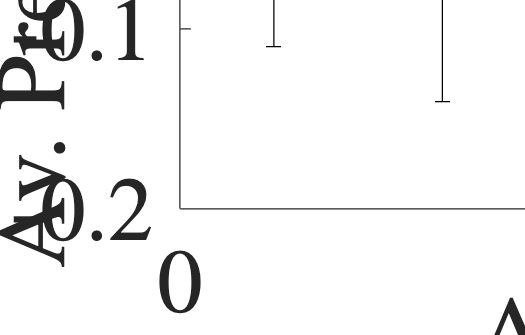

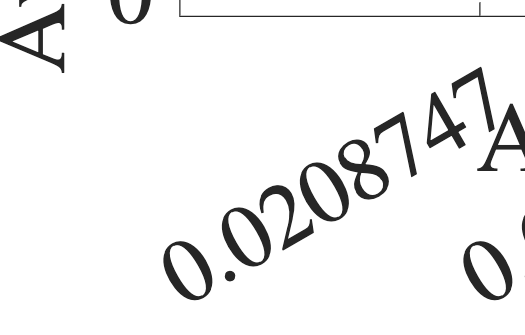


laghr= 10; %hrs
cd(workdir)
antecedent_check(workdir,workdirfig,printfig,laghr,colNums,lagQrange)

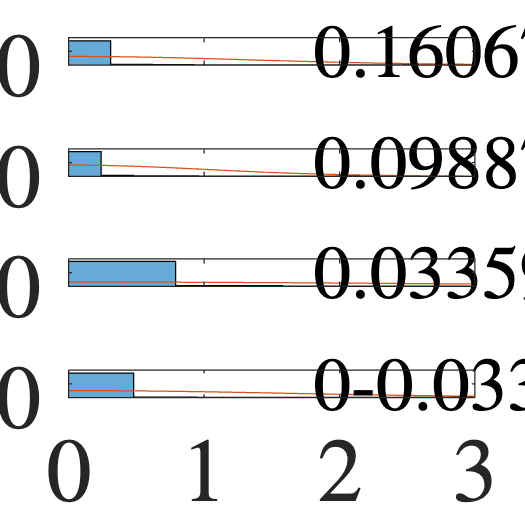

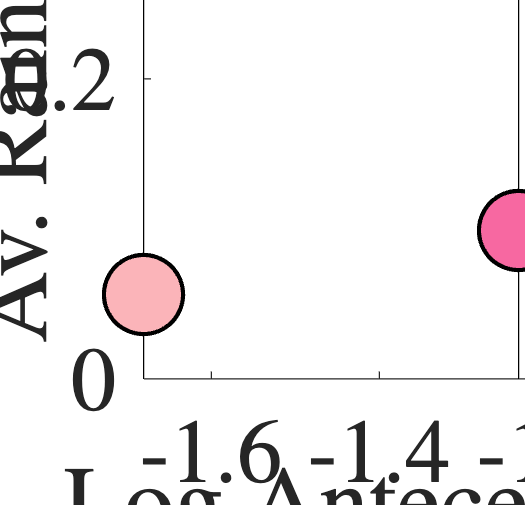


antecedent_check_runoff(workdir,workdirfig,printfig,laghr,colNums,lagQrange)